# The Flatlands Challenge

#### Authors: Dexter Friis-Hecht, Dokyun Kim, Ellen Sun

!!! MATLAB Symbolic Toolbox is required to run the livescript !!!

Given an equation of a "mountain" in 3D space, guide the Neato to the top of the mountain. 

The mountain is defined below.


$$z=16e^{\frac{-x^2}{2} - \frac{y^2}{2} -\frac{xy}{2}}+4e^{-(x+1.5)^2 - (y+2.5)^2}$$


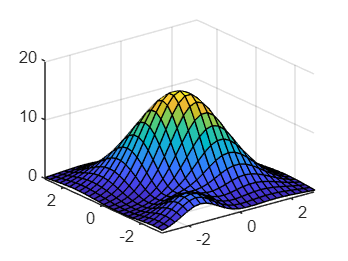

% Plot the mountain in 3D space
clf
X = -3:0.25:3;
[x,y] = meshgrid(X);
f = 16*exp(-x.^2./2-y.^2./2-x.*y./2) + 4*exp(-(x+1.5).^2 - (y+2.5).^2);
surf(x,y,f)

## Gradient Ascent/Descent

In order to program the Neato to climb the mountain, we need to use gradient ascent (or descent). 

Gradient ascent (or descent) is a technique used to determine the maximum (or minimum) of a function of many variables by taking steps in the direction of the gradient (or negative gradient).

Given a function $z = f(r)$, where $r$ is the position vector in the plane, the points determined by the gradient ascent algorithm are defined as:


$$r_{i+1} =r_i+\lambda_i\nabla f(r_i), i=0,1,2,...$$


clc, clear all
syms x y
assume(x, 'real')
assume(y, 'real')

%Function of the mountain
f = 16*exp(-x.^2./2-y.^2./2-x.*y./2) + 4*exp(-(x+1.5).^2 - (y+2.5).^2);

%Declare initial values
grad = gradient(f);
r_x = -2;
r_y = 0;
lambda = 0.1;
delta = 0.8;
r_xes = [r_x; 0]; %Matrix to store x positions
r_yes = [r_y; 0]; %Matrix to store y positions

max_count = 40;
count = 1;
grad_r = double(subs(grad, {x, y}, {r_x, r_y}));

%Calculate every position the Neato using gradient ascent
%Store the x,y positions in a matrix
while abs(norm(grad_r)) > 0.00001 && count <= max_count
    count = count + 1;
    grad_r = double(subs(grad, {x, y}, {r_x, r_y})); %Find gradient vector
    r_x = r_x + lambda*grad_r(1); %Find x
    r_y = r_y + lambda*grad_r(2); %Find y
    lambda = delta * lambda; %update lambda
    r_xes(count) = r_x;
    r_yes(count) = r_y;
end

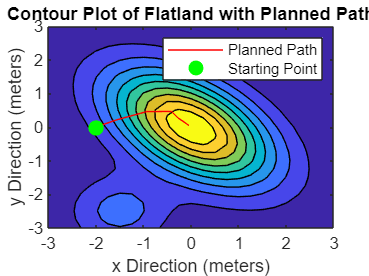

%Plot the path on a 2D contour plot of the mountain
X = -3:0.25:3;
Y = X;
[x2,y2] = meshgrid(X);
contourf(x2, y2, f, 9)

hold on
plot(r_xes, r_yes, "r")
plot(-2, 0, "g.", "MarkerSize", 25)
legend("", "Planned Path", "Starting Point")
xlabel("x Direction (meters)")
ylabel("y Direction (meters)")
title("Contour Plot of Flatland with Planned Path")
hold off